%syms t0
k=398600; 
dt=10; % time step interval
r=6678; % radius
w=sqrt(k/(r^3)); % angular velocity

A=[0,1,0,0;3*w^2,0,0,2*r*w;0,0,0,1;0,-2*w/r,0,0] 

A =          0    1.0000         0         0
    0.0000         0         0   15.4517
         0         0         0    1.0000
         0   -0.0000         0         0


B=[0,0;1,0;0,0;0,1/r]

B =          0         0
    1.0000         0
         0         0
         0    0.0001


C= [1,0,0,0;0,0,1,0]

C =      1     0     0     0
     0     0     1     0


D=zeros(2)

D =      0     0
     0     0


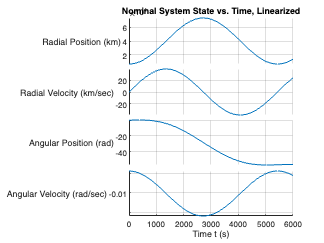


Phi = expm(A);
% Part C
t = 0:10:6000; % time vector (s)
x0=[r;0;0;w]; % Initial conditions

x = zeros(4, length(t)); % States (rad/s)

for i = 1:length(t)
    x(:, i) = expm(A*t(i))*x0;
end
xnom=x';
figure;
s=stackedplot(t, x');
xlabel('Time t (s)');
s.DisplayLabels={'Radial Position (km)', 'Radial Velocity (km/sec)', 'Angular Position (rad)', 'Angular Velocity (rad/sec)'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('Nominal System State vs. Time, Linearized');
grid on;